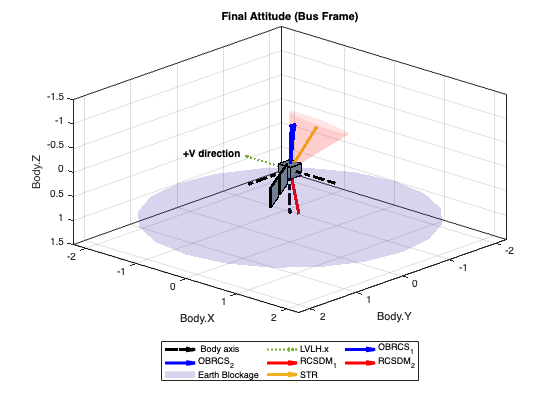

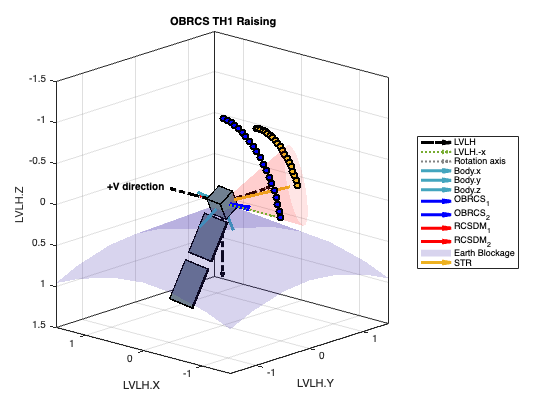

THR_TRACE =     0.0465    0.0794   -0.9958
   -0.0360    0.0548   -0.9978
   -0.1189    0.0319   -0.9924
   -0.2014    0.0108   -0.9795
   -0.2829   -0.0084   -0.9591
   -0.3627   -0.0254   -0.9315
   -0.4402   -0.0402   -0.8970
   -0.5148   -0.0525   -0.8557
   -0.5859   -0.0624   -0.8080
   -0.6528   -0.0698   -0.7543


STR_TRACE =          0    0.6428   -0.7660
   -0.0529    0.6243   -0.7794
   -0.1071    0.6067   -0.7877
   -0.1620    0.5899   -0.7911
   -0.2174    0.5741   -0.7894
   -0.2727    0.5595   -0.7827
   -0.3275    0.5462   -0.7710
   -0.3813    0.5342   -0.7544
   -0.4338    0.5238   -0.7331
   -0.4845    0.5149   -0.7072


clear;
close all; clc

%% PRE-STEP:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Get the path of the current directory and construct the path
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

src_path = fullfile(pwd, 'src');
addpath(genpath(src_path))


%% STEP #1:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Turn on/off for STR Earth blockage cone view
%  0 : disable (no cone display)
%  1 : enable  (plot view cone)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Flag_View = 1;


%% NOTE:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Quaternions here are defined in a specific frame of reference 
%  Import Body-frame --> LVLH quaternion 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%% RESULT:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Run the ATTITUDE_animation function below to view the result
%
%  INPUT:
%   @param Q            :  (1x4)     Quaternion applied to target vector
%   @param component    :  (string)  Component wish to observe
%                                    List:
%                                    1. OBRCS_1
%                                    2. OBRCS_2
%                                    3. RCSDM_1
%                                    4. RCSDM_2 (not working)
%                                    5. Star Tracker (on as default)
%   @param flag         :  (state)   View flag defined in STEP #1
%   @param string       :  (string)  Desired plot name
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% raising, OB1_part
q = [0.1600 0.7055 0.2057 0.6591];
string = 'OBRCS TH1 Raising';
component = 'OBRCS_1';


% MAIN
[THR_TRACE, STR_TRACE] = ATT_animation(q, component, Flag_View, string)